# Finding a 2D SSM from sloshing data

This is an example of how a slow 2D SSM can be fitted to experiment data to predict the system's forced response. This example uses measurements of the center of mass displacement of the liquid in a horizontally excited sloshing tank [1].

clearvars
close all
clc

[1] B. Bäuerlein and K. Avila, Phase-lag predicts nonlinear response maxima in liquid-sloshing experiments, *Journal of Fluid Mechanics* 925 (2021) A22. [https://doi.org/10.1017/jfm.2021.576](https://doi.org/10.1017/jfm.2021.576)

## Example setup

The data consists of three decaying center of mass signals, along with data points of the forced response at three forcing amplitudes. SSMLearn is trained only on the decaying data and predicts a forced response that agrees well with the data points from the forced system. The experiment setup is shown below [1]. 

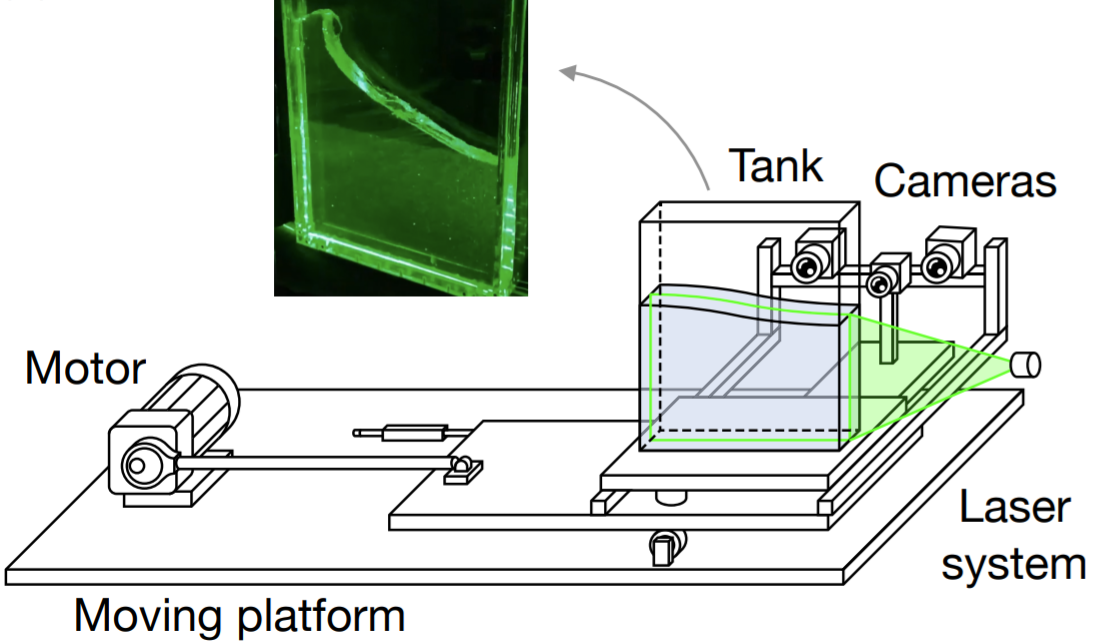

The training trajectories were measured by exciting the tank and then detaching the motor, at three different frequencies, allowing free resonance decay. The data is assumed to lie close to the slowest 2D SSM.

datadir = 'frcdata/';
frcExp{1} = load([datadir,'Measurements_A=0.09%.txt']);
frcExp{2} = load([datadir,'Measurements_A=0.17%.txt']);
frcExp{3} = load([datadir,'Measurements_A=0.32%.txt']);
amplitudes = [0.09, 0.17, 0.32];

load decaydata
decayFrequencies = [0.960,0.967];
width = 500;
for iFreq = 1:length(decayFrequencies)
    titles{iFreq} = ['$\Omega = ', num2str(decayFrequencies(iFreq)), '$'];
end
indTrain = 2;
indTest = 1;

## Delay embedding

Now we arrange the scalar measurements in an observable space of dimension at least $2m+1$, with $m$ the dimension of the manifold. This guarantees that the manifold from the full state space can be embedded in the observable space.

We form a multi-dimensional observable by stacking $d$ subsequent scalar measurements $x$ in a vector $y$, and we will later use the trajectories in this augmented space for the manifold fitting.


$$\left[\begin{array}{c}y_{1} \\ \vdots \\ y_{i+1} \\ \vdots \\ y_{d+1}\end{array} 
\right] = \left[\begin{array}{c}x(t^k) \\ \vdots \\ x(t^k+i\Delta t) \\ \vdots 
\\ x(t^k+d\Delta t)\end{array} \right]$$


The total number of embedded coordinates is $2m+1 + \texttt{overEmbed}$.

SSMDim = 2;
overEmbed = 9;
shiftSteps = 1;
dt = (xData{2,1}(end) - xData{2,1}(1))/(length(xData{2,1})-1);
if dt < 0.03; shiftSteps = 3; end
[yData, opts_embd] = coordinatesEmbedding(xData, SSMDim, 'OverEmbedding', overEmbed, 'ShiftSteps', shiftSteps);

The 15320 embedding coordinates consist of the 1532 measured states and their 9 time-delayed measurements.


embedDim = size(yData{1,2},1)/size(xData{1,2}, 1);
outdof = floor(embedDim/2)*size(xData{1,2}, 1)+1;


## Data filtering

We need to make sure that the data that we use to identify the slow attracting manifold lies close to it. This may not be the case for the very first transient data, as the time series starts at motor detachment. Therefore, we remove some of the initial data. 

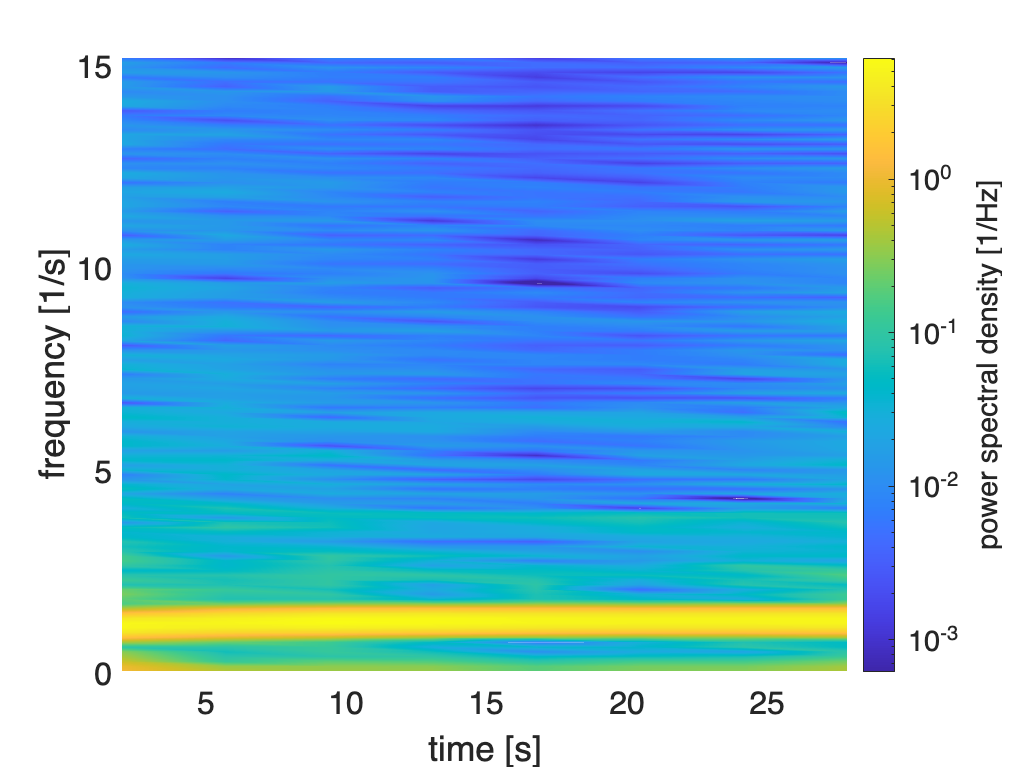

showSpectrogram(xData);

sliceInt = [1.0, Inf];
yData = sliceTrajectories(yData, sliceInt);

## Manifold fitting

The trajectories are assumed to lie close to a two-dimensional manifold that is tangent at the origin to the eigenspace corresponding to the slowest pair of eigenvalues. We now want to fit a polynomial of order $n_{ssm}$ to the data points to approximate the manifold. Here we use a graph style parametrization, meaning that the manifold is parametrized using coordinates in the computed eigenspace $V
$. 

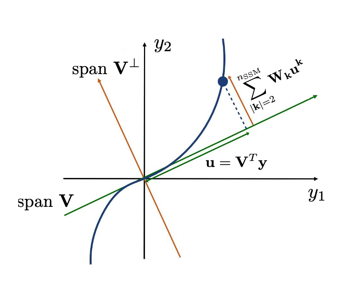

However, we can select the eigenspace to align with the leading singular vectors. This makes identification of the manifold geometry a simple linear regression problem, during which we seek the parametrization of the manifold in the form

${\bf y}={\bf V}{\mathbf{u}}+\sum_{|\mathbf{k}|=2}^{n_{\mathrm{SSM}}}{\bf W}_{\mathbf{k}}{\mathbf{u}}^{\mathbf{k}}$,

where $\mathbf{u}^\mathbf{k}$ contains monomial terms composed of the components of $\mathbf{u}$. This is carried out internally in the function fastSSMplus. 

## Reduced order model

Having computed the tangent space of the manifold, we pass to the reduced coordinates $y$ by projecting all trajectories onto it:

$u= V^T y$.

We compute a model for the reduced dynamics with the truncated training data projected onto the manifold. The function fastSSMplus first directly fits a polynomial map


$$\dot{\bf u}={\bf R}_0{\bf u}+\sum_{|\mathbf{k}|=2}^{n_\mathrm{model}}{\bf R}_{\mathbf{k}}{\bf u}^{\mathbf{k}}$$


The collection (vector) of monomial features $\mathbf{w}^{\mathbf{k}}$ is denoted by $\phi \;\left(w\right)$ and hence the reduced dynamics can be compactly written as


$$\dot{u} =  R_0u + R\phi(u)$$


where $ R
$ is a matrix of the polynomial coefficients. 

After this first regression problem, we transform the dynamics into a format compatible with SSMTool in order to compute the normal-form transformation analytically. The required order of the computation needs to be specified separately. 

Since the dynamics is in normal form, $R^{\text{norm}}
$ contains only coefficients for the near-resonant nonlinear terms, after a near-identity change of coordinates


$$w = T^{-1}(u) = u+ T^{\text{inv}} \phi(u)$$


with $T^{\text{inv}}$ containing the coefficients for the nonlinear terms of the coordinate change. 


 The first 2 nonzero eigenvalues are given as 
  -0.0643 + 7.8157i
  -0.0643 - 7.8157i

sigma_out = 0
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 8.54E-03 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 9.30E-03 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 1.07E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 1.21E-02 MB
\dot{\rho}_1 =
\dot{\theta_1} =


$$\left(\begin{array}{c} -0.0347\,{\rho_{1}}^{5}+0.0018\,{\rho_{1}}^{3}-0.0643\,\rho_{1}\\ 0.0543\,{\rho_{1}}^{4}-0.6046\,{\rho_{1}}^{2}+7.8157 \end{array}\right)$$

gamma = 
   0.0018 - 0.6046i
  -0.0347 + 0.0543i



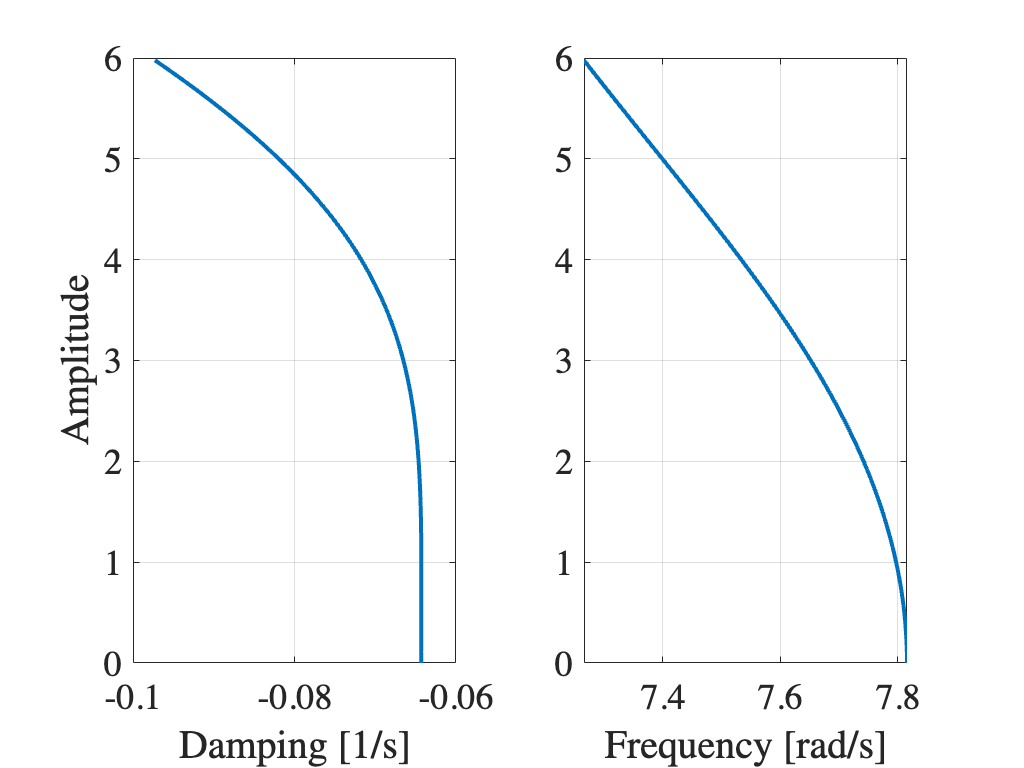

%% Train model
indTest = 1;
indTrain = 2;

SSMOrder = 5;
normalformOrder = 5;

[Mmap, iMmap, Tmap, iTmap, Nflow, yRecF, BBC] = fastSSMplus(yData(indTrain,:), SSMDim, ...
    SSMOrder, normalformOrder, normalformOrder);

%[Mmap, iMmap, Tmap, iTmap, Nflow, yRecF, BBC] = fastSSM(yData(indTrain,:), SSMOrder);

zDataTrunc = transformTrajectories(@(y) iTmap(iMmap(y)), yData);
zRec = integrateFlows(@(z) Nflow(0,z), zDataTrunc);
yRec = transformTrajectories(@(z) Mmap(Tmap(z)), zRec);

NMTE = computeTrajectoryErrors(yRec, yData, [1,2:embedDim:1535])

NMTE =     0.0199
    0.0162


We plot the manifold and the trajectories in the reduced coordinates.

## Evaluation

The normalized mean trajectory error NMTE is computed as the average distance of the predicted trajectory to the measured one in the observable space, normalized by the observable vector with maximum norm in the data. 

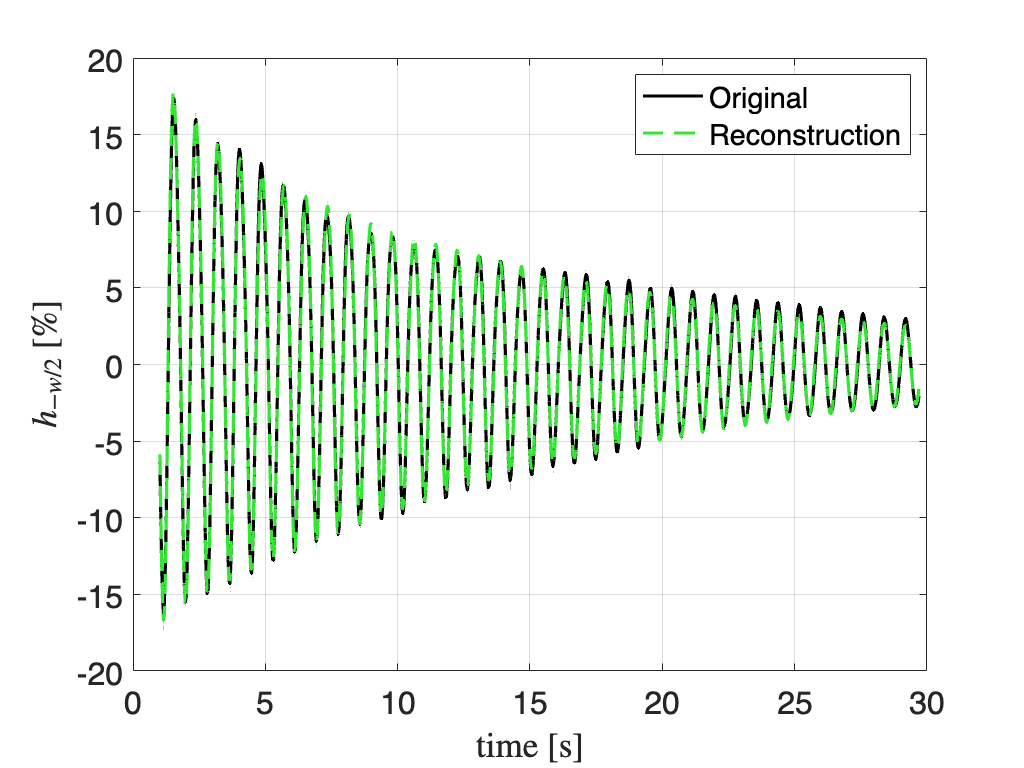

customFigure();
plot(yData{indTest(1),1}(1,:), yData{indTest(1),2}(outdof+1,:), 'Color', [0,0,0], 'LineWidth', 1.6, 'DisplayName', 'Original');
plot(yRec{indTest(1),1}(1,:), yRec{indTest(1),2}(outdof+1,:), '--', 'Color', [0.2,0.9,0.2], 'LineWidth', 1.6, 'DisplayName', 'Reconstruction');
xlabel('time [s]', 'Interpreter', 'latex');
ylabel('$h_{-w/2}$ [\%]', 'Interpreter', 'latex');
legend

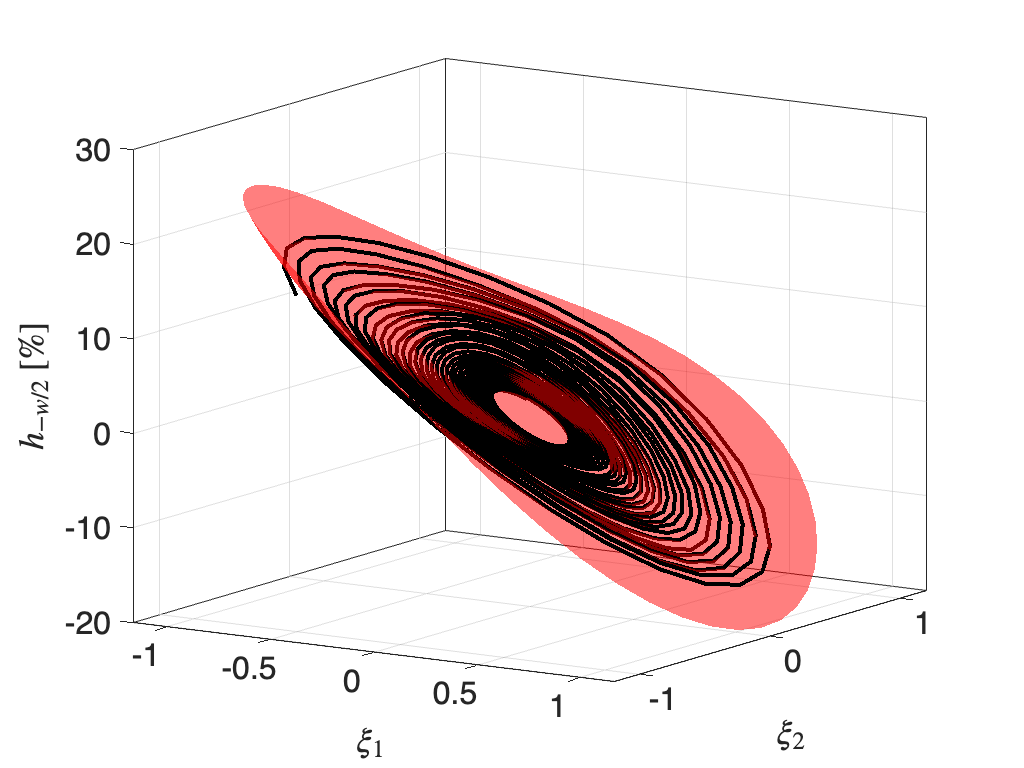


IMInfo = struct();
IMInfo.parametrization.map = Mmap;
IMInfo.parametrization.dimension = SSMDim;
IMInfo.chart.map = iMmap;
plotSSMWithTrajectories(IMInfo, outdof+1, yData(indTrain,:), 'Colors', [0,0,0], 'ColorSurf', 'r')
xlabel('$\xi_1$', 'Interpreter', 'latex'); ylabel('$\xi_2$', 'Interpreter', 'latex');
zlabel('$h_{-w/2}$ [\%]', 'Interpreter', 'latex'); view(33,13)

We plot the measured and predicted center of mass signal for the test trajectory. The reduced model seems to do well on previously unseen data.

## Compute forced response curves

The data-driven model trained on autonomous data can now be used for forced response predictions. With the addition of forcing, the normal form dynamics becomes 

$$\dot{w} =N(w) + f_{red} e^{i\Omega t}$,

where $$\Omega$ is the forcing frequency and $$f_{red}$ is the forcing amplitude. For FRC extraction, we analytically compute fixed points of the polar normal form via a closed form solution.

We need to define the forcing amplitude in the normal form. We do this by passing to `calibrateFRC` a frequency and a point $y_\mathrm{cal}$ in the observable space. At the defined frequency, the calibrated FRC will reach the amplitude of this point. 

The vector $y_\mathrm{cal}$ lies in a delay embedded space, and can be computed either from a delay embedded time-varying response signal, or from a scalar maximal response that is artifically delay embedded. For a scalar value $u_\mathrm{cal}$, this can be achieved by projection onto the tangent space. This method only works for a limited delay embedding dimension. We use the maximal amplitude data point at each forcing level for calibration.

%% FRC
clear yCal Omega
ampF = @(y) abs(y(outdof,:));
w_span = [0.87, 1.06]*7.8;
V = [Mmap(1e-5*[1;0]),Mmap(1e-5*[0;1])]/1e-5;
[~,indV] = max(ampF(V));
for iAmp = 1:length(amplitudes)
    [uCal, pos] = max(frcExp{iAmp}(:,2));
    if iAmp == 4; [uCal, pos] = min(frcExp{iAmp}(:,2)); end
    Omega(iAmp,1) = frcExp{iAmp}(pos,1)*7.8;
    yCal(:,iAmp) = uCal*V(:,indV)./V(outdof,indV);
end


## Plot FRCs

Comparison of the FRCs from SSMLearn with experimental data shows that our autonomous model also predicts the response of the forced system well at these amplitudes, both in terms of amplitude and phase lag.

clear yCal Omega
ampF = @(y) abs(y(outdof,:));
w_span = [0.87, 1.06]*7.8;
V = [Mmap(1e-5*[1;0]),Mmap(1e-5*[0;1])]/1e-5;
[~,indV] = max(ampF(V));
for iAmp = 1:length(amplitudes)
    [uCal, pos] = max(frcExp{iAmp}(:,2));
    if iAmp == 4; [uCal, pos] = min(frcExp{iAmp}(:,2)); end
    Omega(iAmp,1) = frcExp{iAmp}(pos,1)*7.8;
    yCal(:,iAmp) = uCal*V(:,indV)./V(outdof,indV);
end

[fRed, OmegaFm, OmegaFp, uF, psiF] = miniComputeFRC(yCal, Omega, BBC, Mmap, iMmap, Tmap, iTmap, ampF);
%
colors = get(0, 'DefaultAxesColorOrder'); colors = colors(2:end,:);
fig1 = customFigure();
fig2 = customFigure();
for iAmp = 1:length(amplitudes)
    rhoMax = fsolve(@(rho) abs(OmegaFm(rho,fRed(iAmp))-BBC.freq(rho)),0.01);
    rho = linspace(0,rhoMax,100);
    realinds = imag([OmegaFm(rho,fRed(iAmp)), OmegaFp(rho,fRed(iAmp))]) < 1e-3;
    pr = @(x) real(x(:,realinds));
    figure(fig1);
    plot(pr([OmegaFm(rho,fRed(iAmp)), OmegaFp(rho,fRed(iAmp))]), ...
        pr([uF(rho),uF(rho)]), 'Color', colors(iAmp,:), 'Linewidth', 2, ...
        'DisplayName', ['\texttt{fastSSM} $A = ', num2str(amplitudes(iAmp)), ' \%$']);
    plot(frcExp{iAmp}(:,1)*7.8, frcExp{iAmp}(:,2), '.', 'MarkerSize', 16, ...
        'Color', colors(iAmp,:), 'DisplayName', ['Exp. $A = ', num2str(amplitudes(iAmp)), ' \%$'],...
        'MarkerSize', 14)
    figure(fig2);
    plot(pr([OmegaFm(rho,fRed(iAmp)), OmegaFp(rho,fRed(iAmp))]), ...
        -180+180/pi*pr([psiF([rho,rho],fRed(iAmp),[OmegaFm(rho,fRed(iAmp)), OmegaFp(rho,fRed(iAmp))]),...
        psiF([rho,rho],fRed(iAmp),[OmegaFm(rho,fRed(iAmp)), OmegaFp(rho,fRed(iAmp))])]), ...
        'Color', colors(iAmp,:), 'Linewidth', 2, ...
        'DisplayName', ['\texttt{fastSSM} $A = ', num2str(amplitudes(iAmp)), ' \%$']);
    plot(frcExp{iAmp}(:,1)*7.8, frcExp{iAmp}(:,3), '.', 'MarkerSize', 16, ...
        'Color', colors(iAmp,:), 'DisplayName', ['Exp. $A = ', num2str(amplitudes(iAmp)), ' \%$'],...
        'MarkerSize', 14)
end


Equation solved, inaccuracy possible.

The vector of function values is near zero, as measured by the value
of the function tolerance. However, the last step was ineffective.

<stopping criteria details>

Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance 

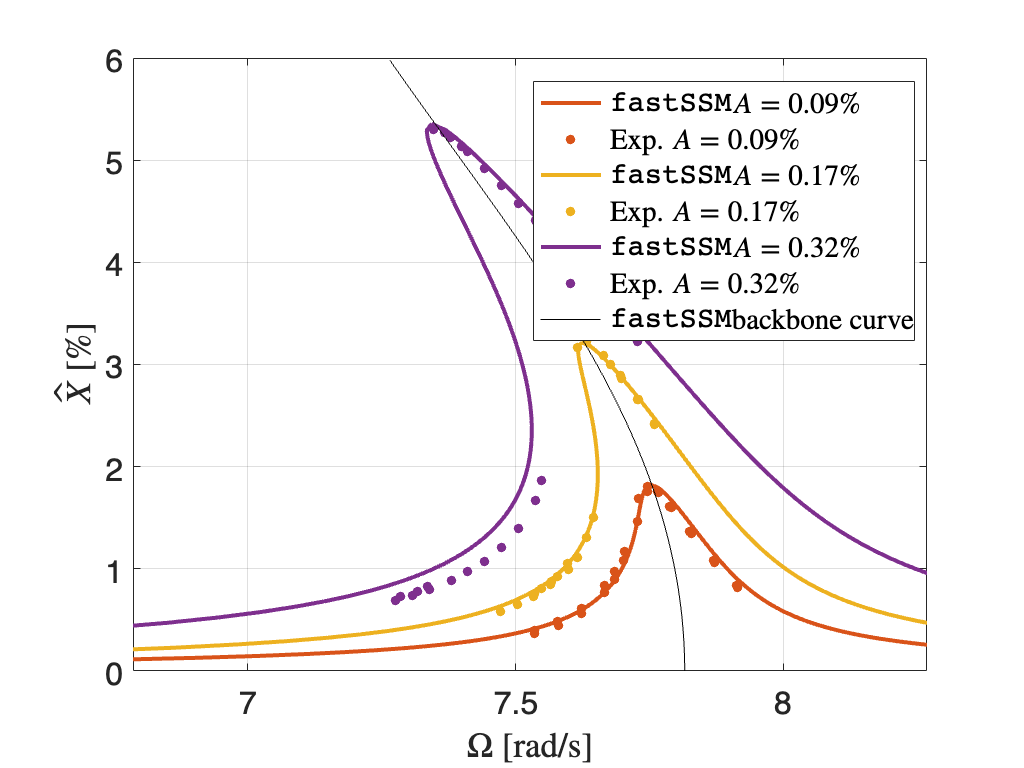

figure(fig1);
plot(BBC.frequency, BBC.amplitude, 'k', 'DisplayName', '\texttt{fastSSM} backbone curve')
xlim(w_span)
ylim([0,6]);
legend('Interpreter', 'latex', 'location', 'best')
xlabel('$\Omega$ [rad/s]', 'Interpreter', 'latex')
ylabel('$\hat{X}$ [\%]', 'Interpreter', 'latex')

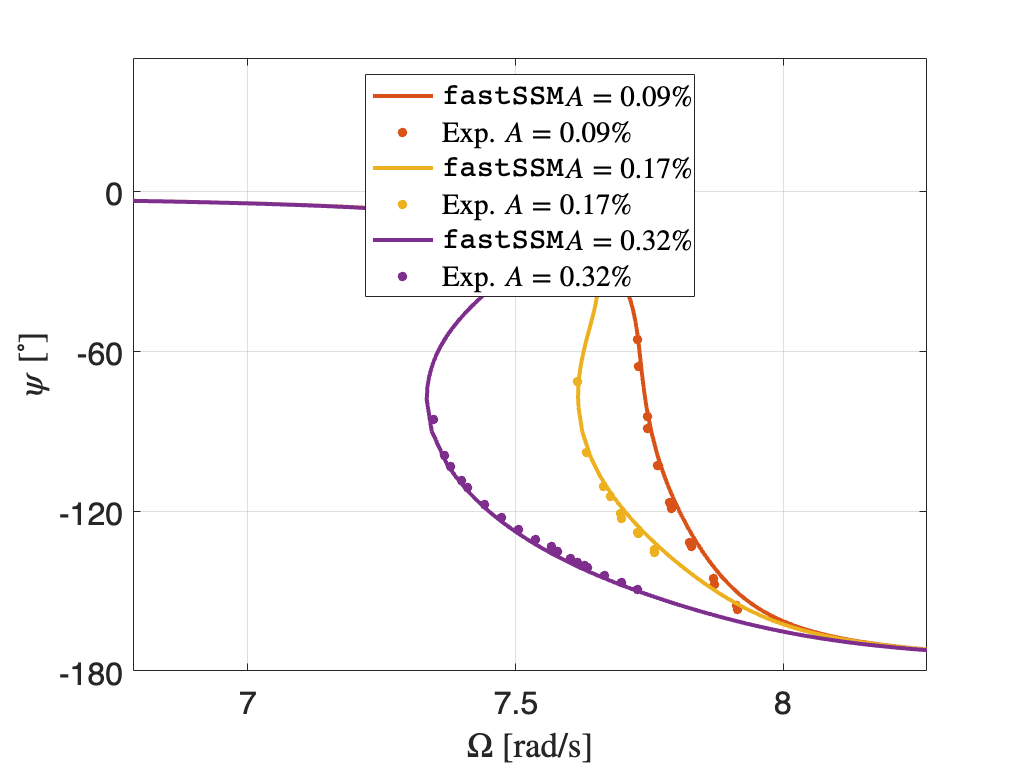


figure(fig2);
xlim(w_span)
ylim([-180,50])
yticks([-180,-120,-60,0]);
legend('Interpreter', 'latex', 'location', 'north')
xlabel('$\Omega$ [rad/s]', 'Interpreter', 'latex')
ylabel('$\psi$ [$^\circ$]', 'Interpreter', 'latex')